clear variables;

RH = transpose([ 11 30 60 80 12 32 68 20 48 72]);
Vm = transpose([ 400 800 1400 2000 400 800 1600 500 900 1300]);
T = transpose([10 10 10 10 0 0 0 -10 -10 -10]);
vector = transpose(ones(1,length(RH)));
params = regress(RH,[Vm,T,vector])

params =     0.0475
   -0.6462
   -4.0454


a=params(1)

a = 0.0475

b=params(2)

b = -0.6462

c=params(3)

c = -4.0454


RH_approx = a*Vm+b*T+c

RH_approx =     8.4989
   27.5055
   56.0154
   84.5252
   14.9612
   33.9678
   71.9809
   26.1751
   45.1817
   64.1883


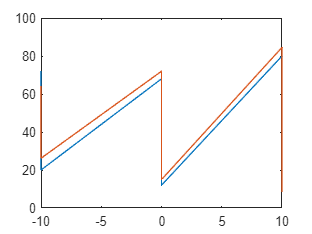


figure,
plot(T,RH);
hold on;
plot(T,RH_approx)